# Presenting Tropical Cyclone Paths

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Download the Data

[The LoadStormData script](matlab: edit LoadStormData.mlx) in the FunctionLibrary folder downloads, processes, and saves storm track data from the [NOAA Hurricane database](https://www.nhc.noaa.gov/data/hurdat/) into the Data folder. 

LoadStormData

allStorms.csv exists, no new download needed
MAT files saved in C:\Users\esmithzb\OneDrive - MathWorks\Scripts\Curriculum Modules\Mathematics\Numerical-Methods-with-Applications\Data


1) Choose the storm you want to track by selecting a value from 1 to 1005.

storm = 301;
load allStorms.mat
myStorm = allStorms(storm);

 Choose various storms such as:

1) Annette, storm number 8

2) Miriam, storm number 301

3) Olivia, storm number 818

4) Raymond, storm number 840

5) Norbert, storm number 1003

disp("My storm is named "+myStorm.Name)

My storm is named MIRIAM


## Plot the Storm Track

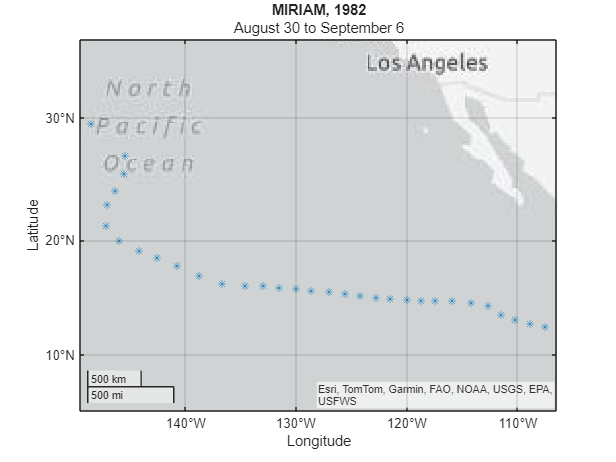

% Plot the path of the storm on a map using the latitude and longitude
% values. Can you tell how the storm was moving?
mapOfStorm = geoplot(myStorm.Lat,myStorm.Long,"*");
title(myStorm.Name + ", " + myStorm.Year)
startingMonth = month(myStorm.StartTime,"name");
endingMonth = month(myStorm.EndTime,"name");
subtitle(startingMonth{1} + " " + day(myStorm.StartTime) + " to " ...
    + endingMonth{1} + " " + day(myStorm.EndTime))

## Animate the Storm Track

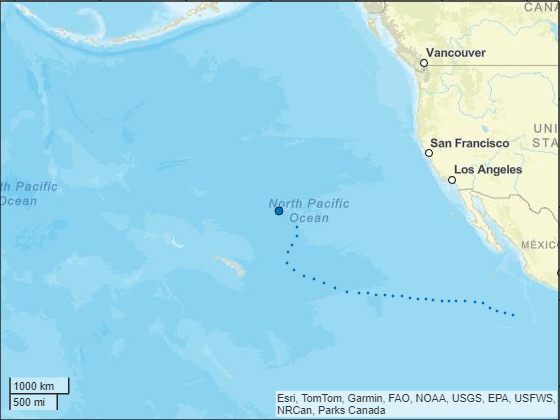

% Choose an appropriate zoom level to see the entire storm track and
% animate the path of the storm. Which direction do you think it is moving?
zoomLevel = 3;
player = geoplayer(mean(myStorm.Lat),mean(myStorm.Long),zoomLevel,"HistoryDepth",Inf);
for i = 1:length(myStorm.Lat)
    plotPosition(player,myStorm.Lat(i),myStorm.Long(i));
    pause(0.1)
end

 **Reflect**.

- What type of curve do you want to use to describe the path of a tropical cyclone?

- What type of curve do you want to use to predict the path of a tropical cyclone?

- How might you try to test your predictions against reality?

## Add detail to the storm track

You can use the built-in `spline` or `pchip` interpolators or use your own. 

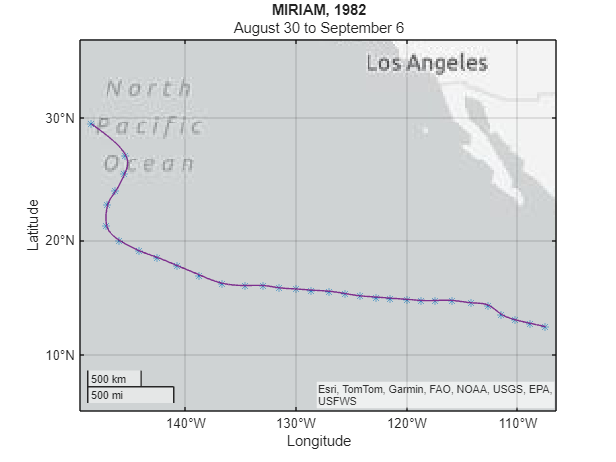

% Set up a time-index value in units of hours with the understanding that
% the original data points exist every 6 hours
indexVals = ((1:length(myStorm.Lat))-1)*6;

% Determine the interpolation values
timeInHrs = 0:.2:hours(myStorm.EndTime-myStorm.StartTime);
latInterp = spline(indexVals,myStorm.Lat,timeInHrs);
longInterp = spline(indexVals,myStorm.Long,timeInHrs);

% Plot the more detailed interpolated path
mapOfStorm;
hold on
geoplot(latInterp,longInterp,"-")
hold off

Choose an appropriate zoom level to see the storm track and animate the path of the storm. 

 **Reflect**

- Which direction do you think it is moving?

- If you tried to extrapolate the path of the storm, were you correct? 

- When you interpolate between known locations for the storm, do you believe the path you create?

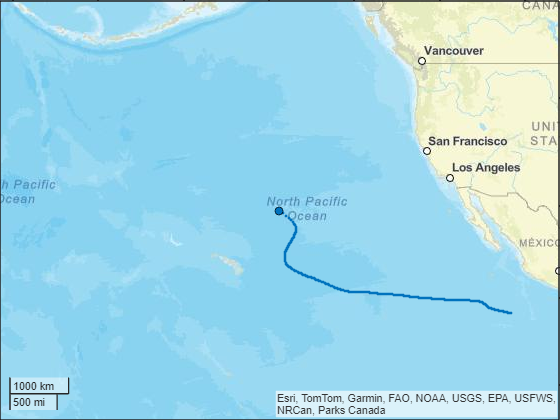

zoomLevel = 3;
player = geoplayer(mean(myStorm.Lat),mean(myStorm.Long),zoomLevel,"HistoryDepth",Inf);
for i = 1:4:length(latInterp)
    plotPosition(player,latInterp(i),longInterp(i));
end

[⇦ Main Menu](matlab:open('MainMenu.mlx'))